# ELEN4006A - Error Measurement Systems 

# Lab - Measurements of Sound

## Sampling Music from File

[x, Fs] = audioread('track.mp3');	% load an audio file
x = x(:, 1);                     	% get the first channel
N = length(x);                   	% signal length
t = (0:N-1)/Fs;

## Time Domain Represenation of Signal

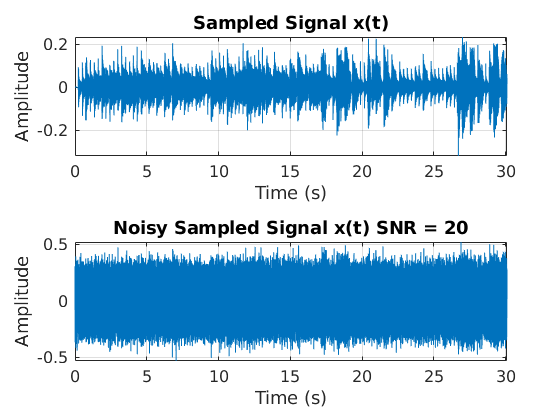

tiledlayout(2,1)

nexttile
plot(t, x)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
xlabel('Time (s)')
ylabel('Amplitude')
title('Sampled Signal x(t)')
xlim([min(t) max(t)]);
ylim([min(x) max(x)]);
SNR = 20;
x_noise = awgn(x, SNR);

nexttile
plot(t, x_noise)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
xlabel('Time (s)')
ylabel('Amplitude')
title("Noisy Sampled Signal x(t) SNR = " + SNR)
xlim([min(t) max(t)]);

Amplitude seems kinda small (mp3 reading normalisation??)

Maybe get a flac or wav file from an online resource and just specify the length

## Signal Power Measurement

pRMS = rms(x)^2

pRMS = 0.0014

powbp = bandpower(x,Fs,[0 Fs/2])

powbp = 0.0014

Verifies that the bandpower is defined correctly in terms of the RMS power

powerPercent = 90

powerPercent = 90

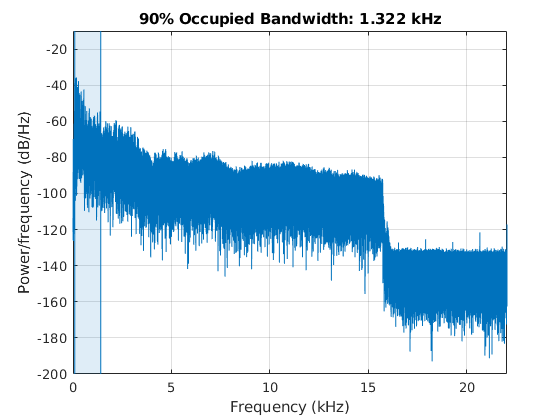

ans = 1.3223e+03

figure
obw(x, Fs, [], powerPercent)

pow99 = obw(x,Fs, [], powerPercent);

## Fourier Analysis

X = fft(x);

Compute the two-sided spectrum `P2`. Then compute the single-sided spectrum `P1` based on `P2` and the even-valued signal length N.

https://www.mathworks.com/help/releases/R2020a/matlab/ref/fft.html#buuutyt-9

P2 = abs(X/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;

### Single Sided Amplitude Spectrum

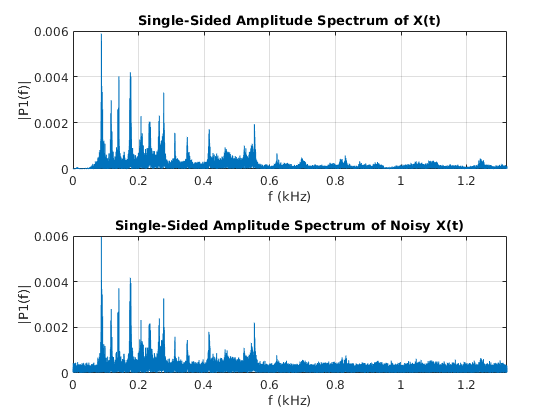

tiledlayout(2,1)

nexttile
h = plot(f/1000,P1);
grid on
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (kHz)')
ylabel('|P1(f)|')
ax = ancestor(h, 'axes');
ax.YAxis.Exponent = 0;
xlim([0 pow99/1000])
X = fft(x_noise);
P2 = abs(X/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;

nexttile
h = plot(f/1000,P1);
grid on
title('Single-Sided Amplitude Spectrum of Noisy X(t)')
xlabel('f (kHz)')
ylabel('|P1(f)|')
ax = ancestor(h, 'axes');
ax.YAxis.Exponent = 0;
xlim([0 pow99/1000])

### fftShift

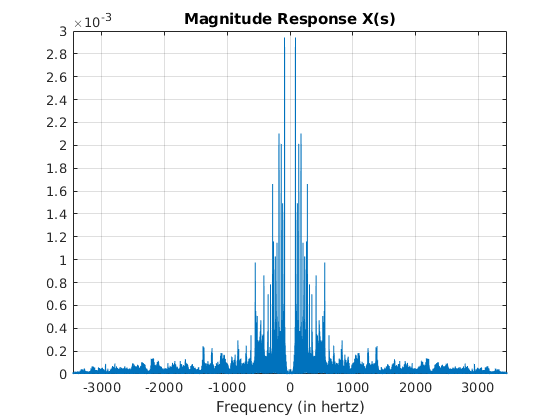

X = fftshift(fft(x));
%% Frequency specifications:
dF = Fs/N;                      % hertz
f = -Fs/2:dF:Fs/2-dF;           % hertz
%%Plot the spectrum:
figure;
plot(f,abs(X)/N);
grid on
xlabel('Frequency (in hertz)');
title('Magnitude Response X(s)');
xlim([-3456 3456])
yticks(0:0.0002:0.003)
ylim([0.00000 0.00300])

index = find(f == 0);
power = sum(abs(X))

power = 1.3866e+07

%format long g
power90 = 0.90*power;
sum_ = abs(X(index));
count = 0;
while sum_ < power90
    count = count + 1;
    sum_ = sum_ + abs(X(index+count)) + abs(X(index-count));
end

90% power

power90

power90 = 1.2479e+07

At freq.

f(index+count)

ans = 7.5225e+03

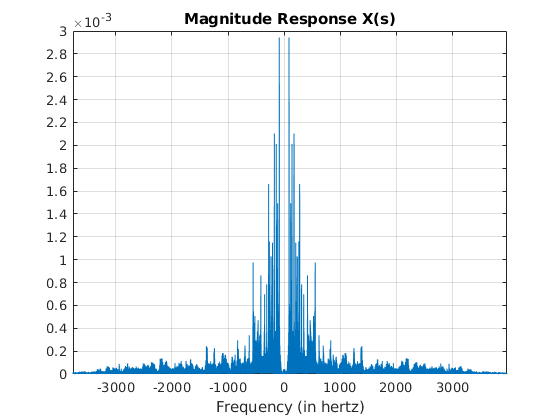

figure;
plot(f,abs(X)/N);
grid on
xlabel('Frequency (in hertz)');
title('Magnitude Response X(s)');
xlim([-3761 3969])
yticks(0:0.0002:0.003)
ylim([0.00000 0.00300])

sum(X(index-count:index+count))

ans = 1.1622e+04 + 2.1373e-11i